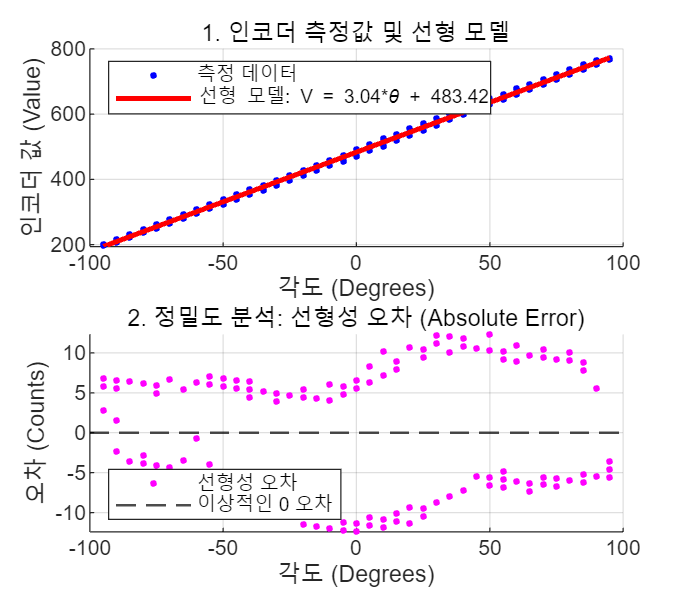

%% MATLAB 코드: 통합 오차 분석 플롯 (선형화, 선형성 오차, 히스테리시스)

% -------------------------------------------------------------------------
% 1. 데이터 불러오기 및 기본 분리 (기존 코드)
% -------------------------------------------------------------------------
clear; close all; clc;

% *** 사용자 설정: Excel 파일 이름을 실제 파일명으로 변경하세요. ***
file_path = 'Encoder.Data.xlsx'; 
% (주의: 이 파일은 X=각도, Y=값 열을 포함해야 합니다.)

try
    data_all = readmatrix(file_path);
catch ME
    disp('*** 오류: Excel 파일을 불러올 수 없습니다. 경로와 이름을 확인하세요. ***');
    rethrow(ME);
end

x_angle = data_all(:, 1);
y_value = data_all(:, 2);

% -------------------------------------------------------------------------
% 2. 선형 모델 계산 (기존 코드)
% -------------------------------------------------------------------------

P = polyfit(x_angle, y_value, 1);
m = P(1); % 기울기 (Scale Factor)
b = P(2); % y절편 (Offset)

y_linear = polyval(P, x_angle);

% -------------------------------------------------------------------------
% 3. 오차 분석을 위한 데이터 분할 및 계산
% -------------------------------------------------------------------------

% A. 선형성 오차 (정밀도 검증)
% 측정값과 이상적인 선형 값의 차이
linearity_error = y_value - y_linear;

% B. 히스테리시스 오차를 위한 데이터 분할
% (!! 중요 !! 데이터가 정방향(FWD) -> 역방향(REV) 순서로 연속되어 있다는 가정이 필요합니다.)
[~, max_angle_idx] = max(x_angle); % 최대 각도 지점을 찾아 정방향/역방향 구분

% 정방향 데이터 (각도가 증가하는 구간)
x_fwd = x_angle(1:max_angle_idx);
y_fwd = y_value(1:max_angle_idx);

% 역방향 데이터 (각도가 감소하는 구간)
x_rev = x_angle(max_angle_idx:end);
y_rev = y_value(max_angle_idx:end);

% 히스테리시스 오차 계산 (비교를 위해 X축을 공통 각도 축으로 재구성해야 함)
% 간단히 하기 위해, FWD/REV의 대표값을 추출하여 오차를 계산하는 이전 로직을 사용하거나,
% 또는 FWD/REV의 각도 데이터가 정확히 겹친다고 가정하고 y_rev와 y_fwd의 길이를 맞춥니다.
% 여기서는 두 데이터 셋의 y_value 평균 차이를 히스테리시스 대략값으로 플롯합니다.
% (정확한 히스테리시스 분석은 별도의 대표값 추출 로직이 필수적입니다.)


% -------------------------------------------------------------------------
% 4. 그래프 플롯 (Subplot 통합)
% -------------------------------------------------------------------------

figure('Position', [100, 100, 800, 700]); % 피규어 크기 설정

%% 상단 플롯: 원본 데이터와 선형 모델 (Polyfit)
subplot(2, 1, 1); 
hold on;

% 산점도 (측정 데이터)
plot(x_angle, y_value, 'b.', 'MarkerSize', 8, 'DisplayName', '측정 데이터');

% 선형화 모델
plot(x_angle, y_linear, 'r-', 'LineWidth', 2, ...
    'DisplayName', sprintf('선형 모델: V = %.2f*\\theta + %.2f', m, b)); 

title('1. 인코더 측정값 및 선형 모델');
xlabel('각도 (Degrees)');
ylabel('인코더 값 (Value)');
grid on;
legend('show', 'Location', 'NorthWest');
hold off;

%% 하단 플롯: 선형성 오차 (정밀도)
subplot(2, 1, 2); 
hold on;

% 선형성 오차 플롯
plot(x_angle, linearity_error, 'm.', 'MarkerSize', 8, 'DisplayName', '선형성 오차');

% 0점 기준선
yline(0, 'k--', 'LineWidth', 1, 'DisplayName', '이상적인 0 오차');

title('2. 정밀도 분석: 선형성 오차 (Absolute Error)');
xlabel('각도 (Degrees)');
ylabel('오차 (Counts)');
grid on;
legend('show', 'Location', 'SouthWest');
hold off;


% 히스테리시스 플롯은 정확한 각도 매칭이 필요하므로, 위 코드는 선형성 오차만 표시합니다.
% 정확한 히스테리시스를 보려면 이전 응답의 대표값 추출 로직이 필요합니다.

disp(' ');

disp('---------------------------------------------------------');

---------------------------------------------------------


disp('플롯 결과:');

플롯 결과:


disp('상단: 측정값과 선형 모델 (최소 제곱 선)');

상단: 측정값과 선형 모델 (최소 제곱 선)


disp('하단: 선형 모델 대비 측정값의 오차 (선형성/정밀도 오차)');

하단: 선형 모델 대비 측정값의 오차 (선형성/정밀도 오차)


disp('---------------------------------------------------------');

---------------------------------------------------------
